## Problema 3

Definim functia si derivatele necesare

close all
f = @(x) atan(x);
fd = @(x) 1 ./ (x .^ 2 + 1);
fdd = @(x) - 2 * x ./ (x .^ 2 + 1) .^ 2;

## a) Spline

Calculam nodurile si pregatim argumentele pentru Spline

n = 15;
x_ech = linspace(-1, 1, n); % nodurile echidistante
y_ech = f(x_ech);

k = 0:n;
x_ceb1 = sort(cos(((2 * k + 1) * pi) / (2 * n + 2))); % noduri Cebîșev #1
y_ceb1 = f(x_ceb1);

yd = fd([-1, 1]);
ydd = fdd([-1, 1]);

Calculam coeficientii si evaluam

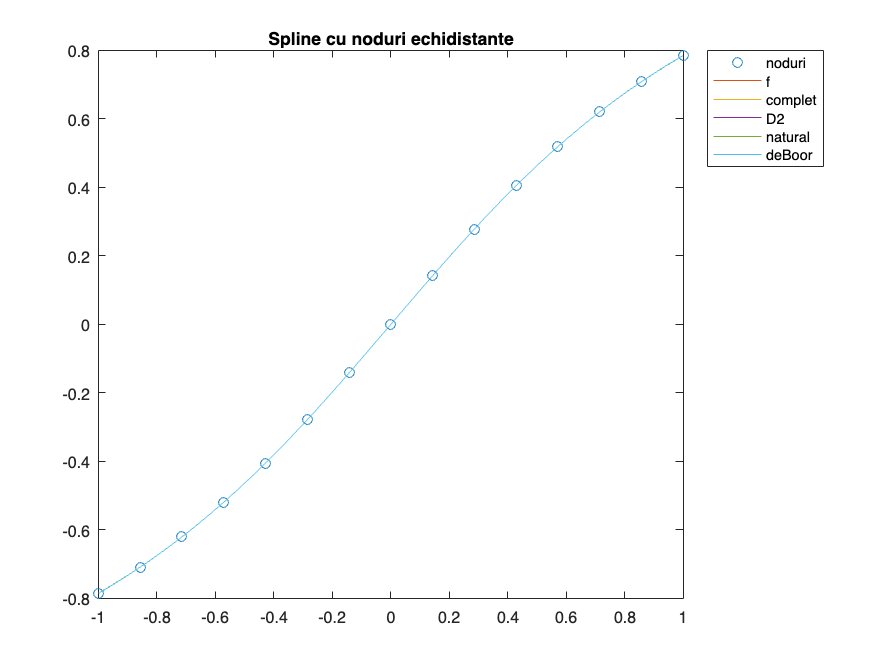

t = linspace(-1, 1, 300); % punctele de evluare

% ech
s_e1 = CubicSpline(x_ech, y_ech, 0, yd);
s_e2 = CubicSpline(x_ech, y_ech, 1, ydd);
s_e3 = CubicSpline(x_ech, y_ech, 2);
s_e4 = CubicSpline(x_ech, y_ech, 3);

z_e1 = EvalSpline(x_ech, s_e1, t);
z_e2 = EvalSpline(x_ech, s_e2, t);
z_e3 = EvalSpline(x_ech, s_e3, t);
z_e4 = EvalSpline(x_ech, s_e4, t);

plot(x_ech, y_ech, 'o', t, f(t), t, [z_e1, z_e2, z_e3, z_e4]);
legend('noduri','f','complet','D2','natural','deBoor','Location','bestoutside')
title('Spline cu noduri echidistante')

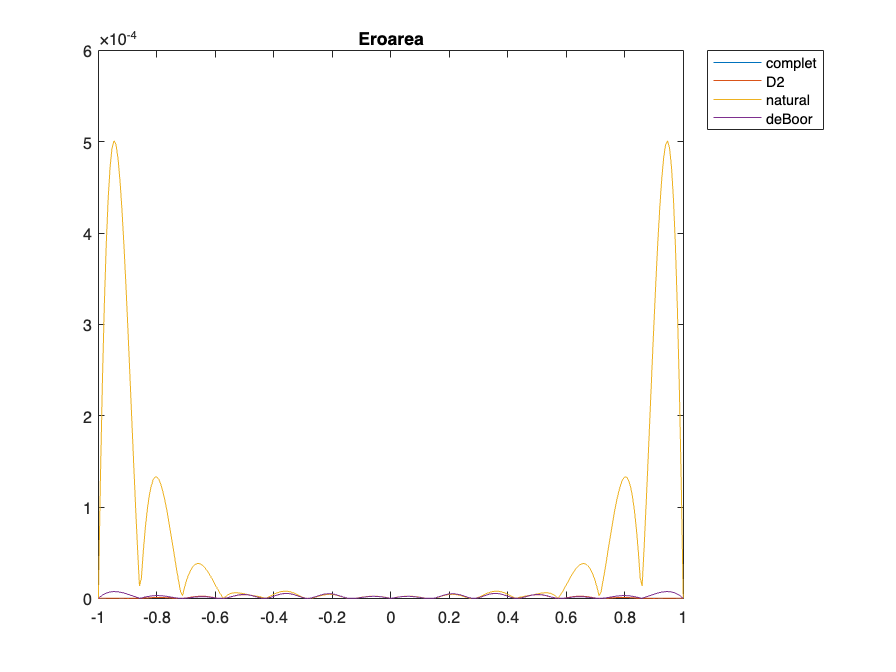

ft = f(t');
plot(t', abs(repmat(ft,1,4)-[z_e1, z_e2, z_e3, z_e4]))
legend('complet','D2','natural','deBoor','Location','bestoutside');
title('Eroarea')

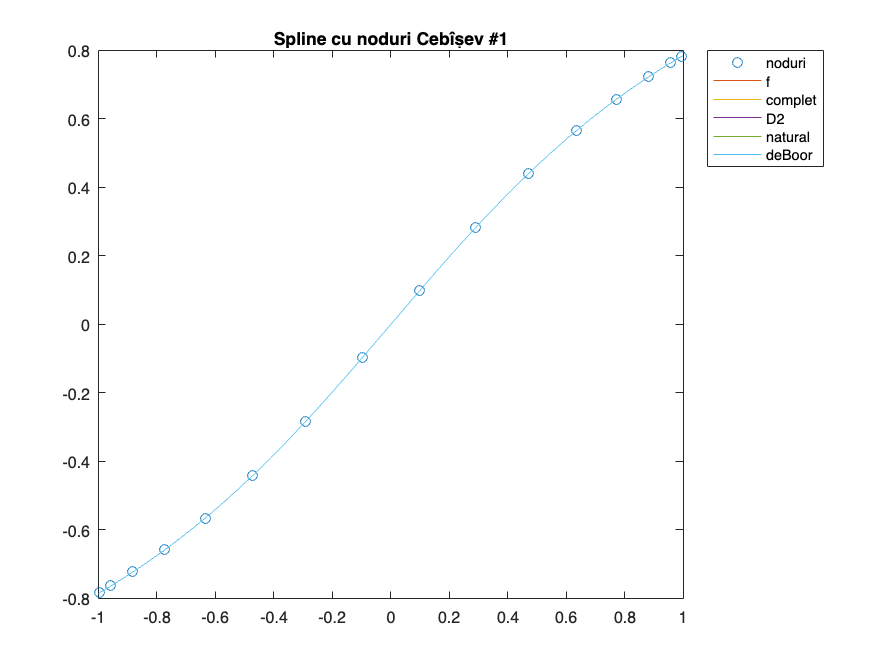

% cheb
s_c1 = CubicSpline(x_ceb1, y_ceb1, 0, yd);
s_c2 = CubicSpline(x_ceb1, y_ceb1, 1, ydd);
s_c3 = CubicSpline(x_ceb1, y_ceb1, 2);
s_c4 = CubicSpline(x_ceb1, y_ceb1, 3);

z_c1 = EvalSpline(x_ceb1, s_c1, t);
z_c2 = EvalSpline(x_ceb1, s_c2, t);
z_c3 = EvalSpline(x_ceb1, s_c3, t);
z_c4 = EvalSpline(x_ceb1, s_c4, t);

plot(x_ceb1, y_ceb1, 'o',t, f(t), t, [z_c1, z_c2, z_c3, z_c4])
legend('noduri','f','complet','D2','natural','deBoor','Location','bestoutside')
title('Spline cu noduri Cebîșev #1')

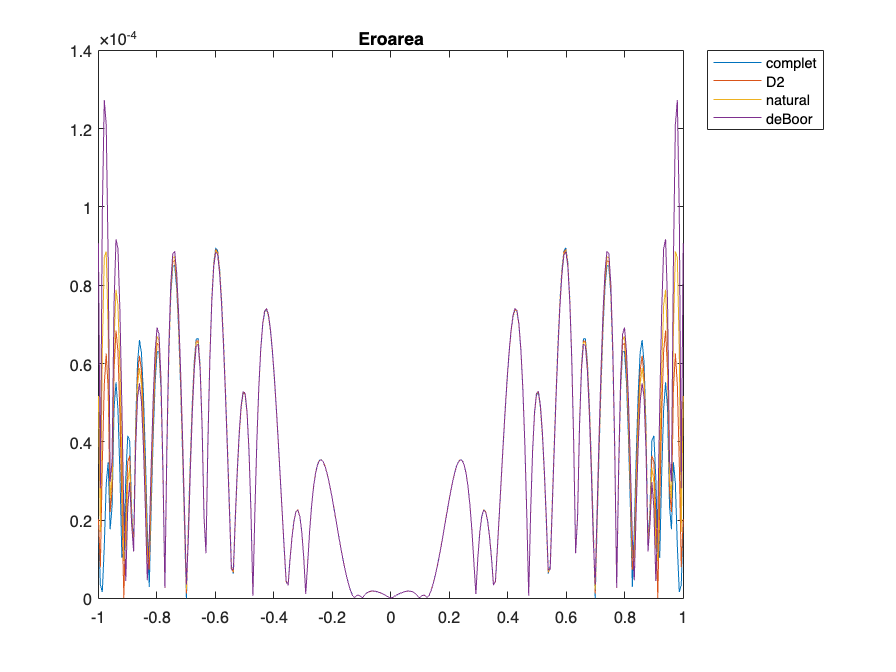

plot(t', abs(repmat(ft,1,4)-[z_c1, z_c2, z_c3, z_c4]))
legend('complet','D2','natural','deBoor','Location','bestoutside');
title('Eroarea')

## b) MCMMP

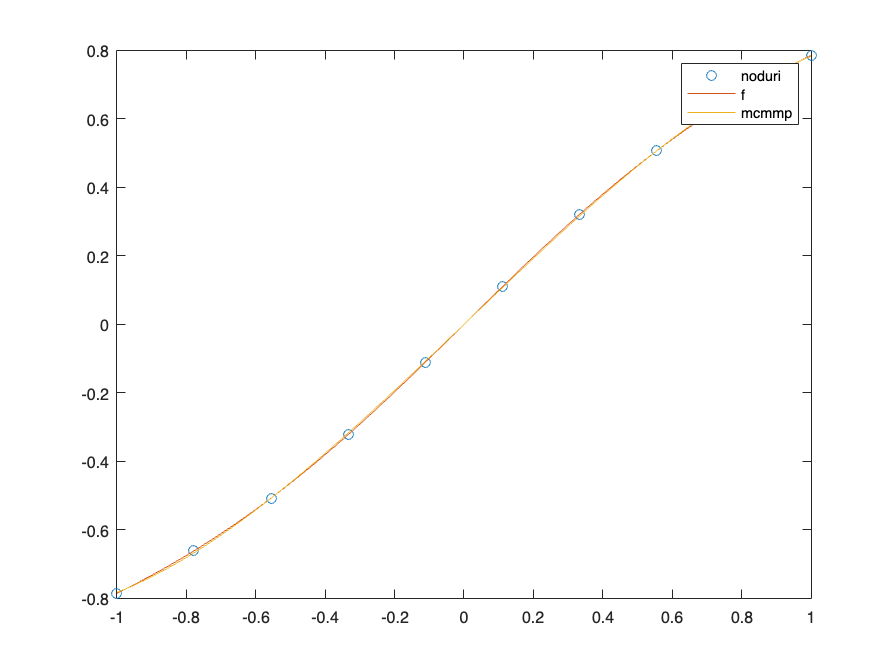

format long
n = 10;
x = linspace(-1, 1, 10);
y = f(x);

% incercam sa modelam printr-un polinom de gradul III functia

A = [ones(size(x)); x; x .^ 2; x .^ 3;]'; % functiile elementare
b = y';
approxLsq = flip(A \ b)';

t = linspace(-1, 1, 300);
xs = polyval(approxLsq, t);
plot(x, y, 'o', t, f(t), t, xs)
legend('noduri', 'f', 'mcmmp')

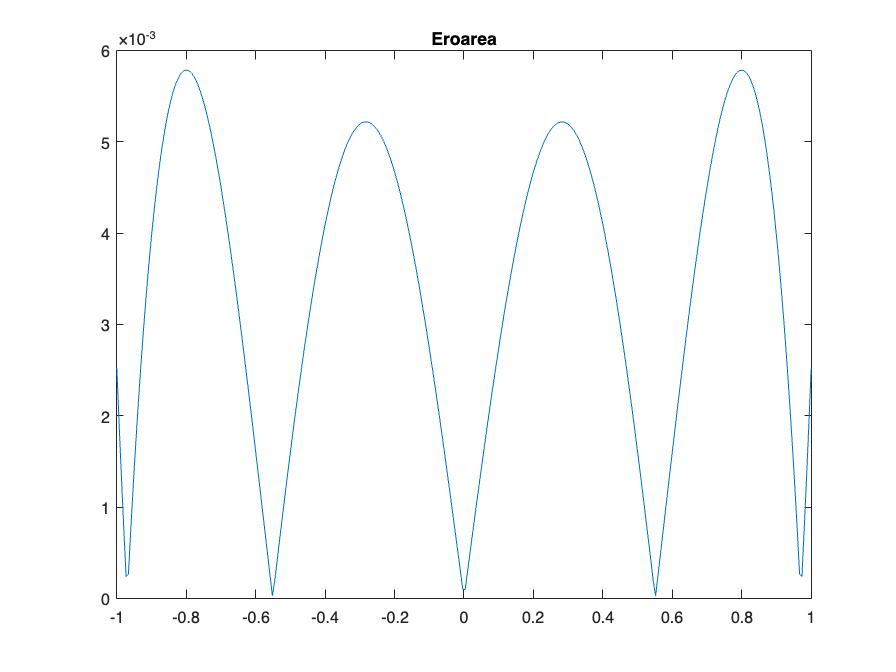

plot(t, abs(f(t) - xs))
title('Eroarea')